# Setup and Open Loop

%This code is a stability analysis for the smooth portion of the hybrid fly
%model.  It serves to investigate the gain space as well as the effects of
%neurological delay.

%Plant model of yaw dynamics 
%From (Elzinga, M. J., Dickson, W. B., & Dickinson, M. H. (2012).
%The influence of sensory delay on the yaw dynamics of a flapping insect.
%Journal of the Royal Society Interface, 9(72), 1685–1696.
%https://doi.org/10.1098/rsif.2011.0699)
clear
Cu = 3.53e3;
Cw = 7.47e2;
I = 1.97e3;
G_plant = tf(Cu,[I Cw]); %Torque to Velocity

# Add Closed Loop Controller (PI) and delay

%PI controller
Kp = 5;
Ki = 30;

C_tf = tf([Kp Ki],[1 0])

%Delay (Pade approximation)
sym s;
td =.08;
s = tf('s');
[nump,denp]=pade(td,3);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = C_tf*G_plant*d_tf;
oltf = minreal(num);
den = (1 + oltf);
cl_tf = num/den;
figure
pzmap(cl_tf);
figure
step(cl_tf);
figure
margin(cl_tf)
figure1=figure('Position', [100, 100, 1024, 1200]);
subplot(2,1,1)
h = nyquistplot(oltf);
p = getoptions(h);
p.XLim = {[-3, 0.5]};
p.YLim = {[-1.5, 1.5]};
setoptions(h,p);
subplot(2,1,2)
pzmap(cl_tf);

# Animation (Increasing Delay)

%PI controller
Kp = 5;
Ki = 30;

C_tf = tf([Kp Ki],[1 0]);
td = 0.01:0.001:0.15;
fig = figure;
for i = 1:size(td,2)
    %Delay (Pade approximation)
    sym s;
    s = tf('s');
    [nump,denp]=pade(td(i),3);
    d_tf = tf(nump,denp);
    
    %Closed Loop Transfer Function
    num = C_tf*G_plant*d_tf;
    oltf = minreal(num);
    den = (1 + oltf);
    cl_tf = num/den;
    
    h = nyquistplot(oltf);
    p = getoptions(h);
    p.XLim = {[-3, .5]};
    p.YLim = {[-1.5, 1.5]};
    setoptions(h,p);
    F(i) = getframe(fig);
end

%Write movie file
v = VideoWriter('NyquistDelay.avi');
open(v)
writeVideo(v,F);
close(v)

# Animation (Increasing Delay, all 4 stability plots)

%PI controller
Kp = 5;
Ki = 30;

C_tf = tf([Kp Ki],[1 0]);
td = 0.01:0.001:0.15;
fig=figure('Position', [100, 100, 1024, 1200]);
clear F
for i = 1:size(td,2)
    %Delay (Pade approximation)
    sym s;
    s = tf('s');
    [nump,denp]=pade(td(i),3);
    d_tf = tf(nump,denp);
    
    %Closed Loop Transfer Function
    num = C_tf*G_plant*d_tf;
    oltf = minreal(num);
    den = (1 + oltf);
    cl_tf = num/den;
    
    subplot(2,2,1)
    nyq = nyquistplot(oltf);
    nyqopt = getoptions(nyq);
    nyqopt.XLim = {[-3, .5]};
    nyqopt.YLim = {[-1.5, 1.5]};
    setoptions(nyq,nyqopt);
    
    subplot(2,2,2)
    pzopt = pzoptions;
%     pzopt.XLim = {[-500, 500]};
%     pzopt.YLim = {[-400, 400]};
    pzmap(cl_tf);

    
    subplot(2,2,3)
    step = stepplot(cl_tf);
    
    subplot(2,2,4)
    bode(cl_tf)
    
    sgtitle(['K_p = 5 , K_i = 30, t_d = ',num2str(td(i))])
    F(i) = getframe(fig);
end

%Write movie file
v = VideoWriter('4PlotsDelay.avi');
v.FrameRate = 6;
open(v)
writeVideo(v,F);
close(v)

# Animation (Increasing Proportional Gain, all 4 stability plots)

%PI controller

Ki = 30;
td = 0.04;
%Delay (Pade approximation)
sym s;
s = tf('s');
[nump,denp]=pade(td,3);
d_tf = tf(nump,denp);

Kp = 0:0.2:30;
fig=figure('Position', [100, 100, 1024, 1200]);
clear F
for i = 1:size(Kp,2)
    
    %Closed Loop Transfer Function
    C_tf = tf([Kp(i) Ki],[1 0]);
    num = C_tf*G_plant*d_tf;
    oltf = minreal(num);
    den = (1 + oltf);
    cl_tf = num/den;
    
    subplot(2,2,1)
    nyq = nyquistplot(oltf);
    nyqopt = getoptions(nyq);
    nyqopt.XLim = {[-3, .5]};
    nyqopt.YLim = {[-1.5, 1.5]};
    setoptions(nyq,nyqopt);
    
    subplot(2,2,2)
    pzmap(cl_tf);

    
    subplot(2,2,3)
    step = stepplot(cl_tf);
    
    subplot(2,2,4)
    bode(cl_tf)
    
    sgtitle(sprintf('K_p = %.1f, K_i = 30, t_d = 0.04',Kp(i)))
    F(i) = getframe(fig);
end

%Write movie file
v = VideoWriter('4PlotsProportional.avi');
v.FrameRate = 6;
open(v)
writeVideo(v,F);
close(v)

# Animation (Increasing Integral Gain, all 4 stability plots)

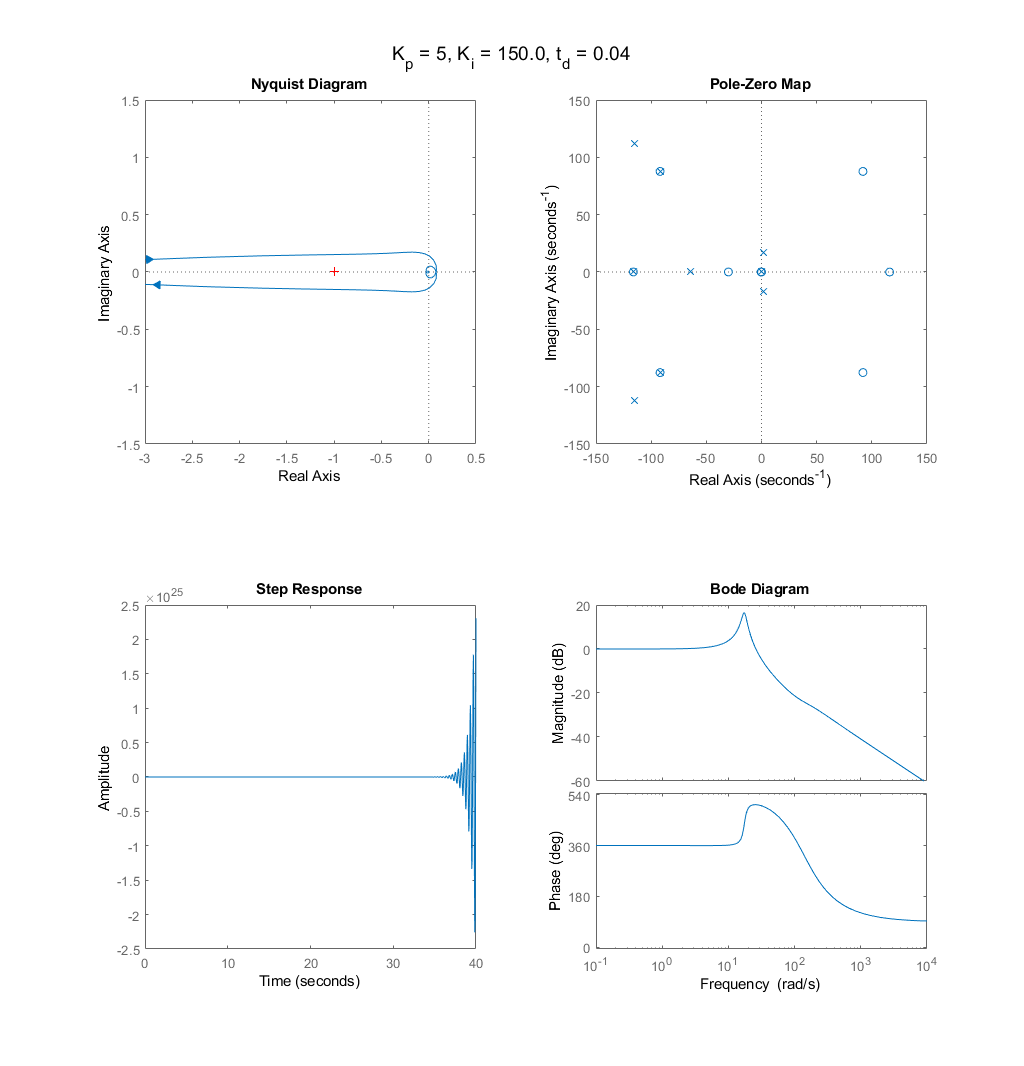

%PI controller

Kp = 5;
td = 0.04;
%Delay (Pade approximation)
sym s;
s = tf('s');
[nump,denp]=pade(td,3);
d_tf = tf(nump,denp);

Ki = 0:2:150;
fig=figure('Position', [100, 100, 1024, 1200]);
clear F
for i = 1:size(Ki,2)
    
    %Closed Loop Transfer Function
    C_tf = tf([Kp Ki(i)],[1 0]);
    num = C_tf*G_plant*d_tf;
    oltf = minreal(num);
    den = (1 + oltf);
    cl_tf = num/den;
    
    subplot(2,2,1)
    nyq = nyquistplot(oltf);
    nyqopt = getoptions(nyq);
    nyqopt.XLim = {[-3, .5]};
    nyqopt.YLim = {[-1.5, 1.5]};
    setoptions(nyq,nyqopt);
    
    subplot(2,2,2)
    pzmap(cl_tf);

    
    subplot(2,2,3)
    step = stepplot(cl_tf);
    
    subplot(2,2,4)
    bode(cl_tf)
    
    sgtitle(sprintf('K_p = 5, K_i = %.1f, t_d = 0.04',Ki(i)))
    F(i) = getframe(fig);
end


%Write movie file
v = VideoWriter('4PlotsIntegral.avi');
v.FrameRate = 6;
open(v)
writeVideo(v,F);
close(v)

# Binary Stability Field

Kp = 1:.2:20;
Ki = 1:.4:40;
td = 0:0.001:0.7;
maxsize = size(Kp,2)*size(Ki,2)*size(td,2);

%Storage arrays preallocated at maximum size - trimmed post loop
stable = zeros(maxsize,3);
st = 1;
unstable = zeros(maxsize,3);
ust = 1;
stabletip = zeros(size(Kp,2)*size(Ki,2),3);
stc = 1;
for i = 1:size(Kp,2)
    tic
    for j = 1:size(Ki,2)
        for k = 1:size(td,2)
            
            %Delay (Pade approximation)
            [nump,denp]=pade(td(k),3);
            d_tf = tf(nump,denp);
            
            %Closed Loop Transfer Function
            C_tf = tf([Kp(i) Ki(j)],[1 0]);
            num = C_tf*G_plant*d_tf;
            den = (1 + num);
            cl_tf = num/den;
            
            %Stability check and array placement
            s = isstablemod(cl_tf);
            if s == 1
                stable(st,:) = [Kp(i) Ki(j) td(k)];
                stt = st;
                st = st + 1;
            else
                unstable(ust,:) = [Kp(i) Ki(j) td(k)];
                ust = ust + 1;    
            end
        end
        stabletip(stc,:) = stable(stt,:);
        stc = stc + 1;
    end
    toc
end

Elapsed time is 385.193077 seconds.
Elapsed time is 383.409262 seconds.
Elapsed time is 383.571166 seconds.
Elapsed time is 384.382497 seconds.
Elapsed time is 383.633992 seconds.
Elapsed time is 383.620294 seconds.
Elapsed time is 383.689388 seconds.
Elapsed time is 383.688597 seconds.
Elapsed time is 383.416631 seconds.
Elapsed time is 382.735809 seconds.
Elapsed time is 382.768929 seconds.
Elapsed time is 382.598501 seconds.
Elapsed time is 383.479044 seconds.
Elapsed time is 383.238368 seconds.
Elapsed time is 383.444473 seconds.
Elapsed time is 383.428234 seconds.
Elapsed time is 383.281535 seconds.
Elapsed time is 383.346340 seconds.
Elapsed time is 382.908401 seconds.
Elapsed time is 383.110308 seconds.
Elapsed time is 383.775407 seconds.
Elapsed time is 384.409468 seconds.
Elapsed time is 382.546547 seconds.
Elapsed time is 382.914515 seconds.
Elapsed time is 383.122437 seconds.
Elapsed time is 382.693221 seconds.
Elapsed time is 383.164371 seconds.
Elapsed time is 382.921481 s

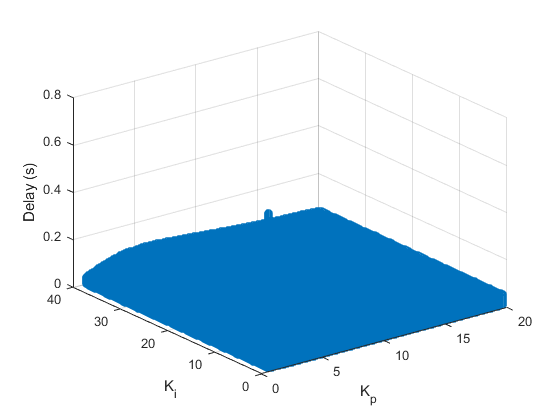


%Trim stability arrays
if st == 1
    stable = [];
else
    stable = stable(1:st-1,:);
end

if ust == 1
    unstable = [];
else
    unstable = unstable(1:ust-1,:);
end



# Surface fit to marginal stability

%Marginal Stability curve fit
%Pick tallest stable point from each kp,ki duplet

sf = fit([stabletip(:,1), stabletip(:,2)],stabletip(:,3),'cubicinterp')

     Piecewise cubic interpolant:
       sf(x,y) = piecewise cubic surface computed from p
     Coefficients:
       p = coefficient structure



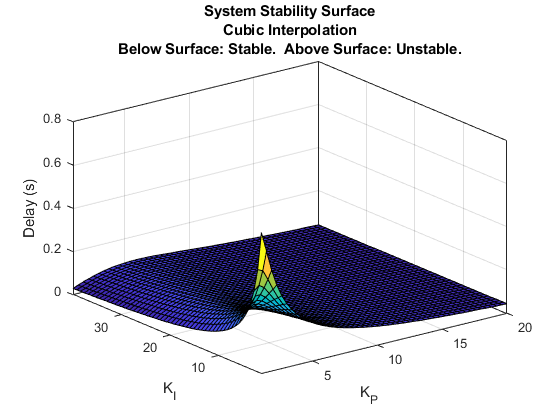

figure
plot(sf)% [stabletip(:,1), stabletip(:,2)],stabletip(:,3))
xlabel('K_P')
ylabel('K_I')
zlabel('Delay (s)')
title({'System Stability Surface', 'Cubic Interpolation', 'Below Surface: Stable.  Above Surface: Unstable.'})

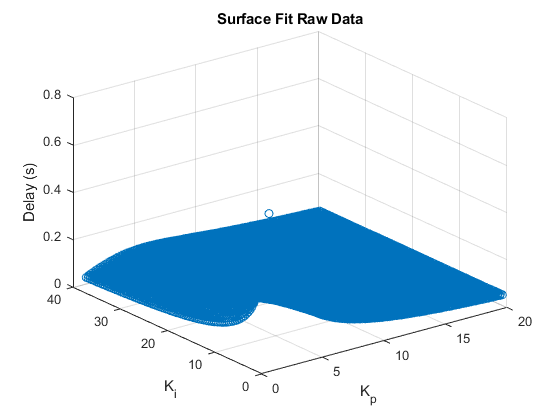

figure
scatter3(stabletip(:,1), stabletip(:,2), stabletip(:,3),'o')
xlabel('K_p')
ylabel('K_i')
zlabel('Delay (s)')
title('Surface Fit Raw Data')

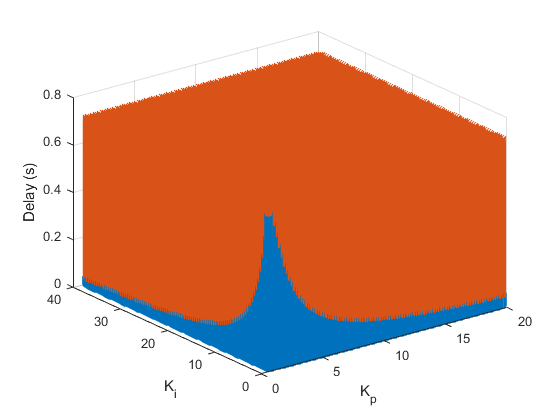


%Plot
if isempty(unstable)
    figure
    scatter3(stable(:,1), stable(:,2), stable(:,3),'o')
    xlabel('K_p')
    ylabel('K_i')
    zlabel('Delay (s)')
elseif isempty(stable)
    figure
    scatter3(unstable(:,1), unstable(:,2), unstable(:,3),'x')
    xlabel('K_p')
    ylabel('K_i')
    zlabel('Delay (s)')
else
    figure
    scatter3(stable(:,1), stable(:,2), stable(:,3),'o')
    hold on
    scatter3(unstable(:,1), unstable(:,2), unstable(:,3),'x')
    xlabel('K_p')
    ylabel('K_i')
    zlabel('Delay (s)')
end